**Data Exploration & Linear Regression Modeling - Seoul Bike Sharing**

Dataset from https://archive.ics.uci.edu/ml/datasets/Seoul+Bike+Sharing+Demand

Christine Kuhn

**Data columns: **

1 - Date : year-month-day, 2 - Rented Bike count - Count of bikes rented at each hour; 3 - Hour - Hour of the day; 4 - Temperature-Temperature in Celsius; 5 - Humidity - %; 6 - Windspeed - m/s; 7 - Visibility - 10m; 8 - Dew point temperature - Celsius; 9 - Solar radiation - MJ/m2; 10 - Rainfall - mm; 11 - Snowfall - cm; 12 - Seasons - Winter, Spring, Summer, Autumn; 13 - Holiday - Holiday/No holiday, 14 - Functional Day - NoFunc(Non Functional Hours), Fun(Functional hours)

**Output variable:**

Column 2 (Rented bike count)

clear all
close all

Read in dataset

dataset=readtable('SeoulBikeData.csv');

dataset = convertvars(dataset, "Date", 'datenum');
dataset = convertvars(dataset, "FunctioningDay", 'string');
dataset = convertvars(dataset, "Holiday", 'string');
dataset = convertvars(dataset, "Seasons", 'string');
seasonnum = double(categorical(dataset.Seasons));
fdaynum = double(categorical(dataset.FunctioningDay));
hdaynum = double(categorical(dataset.Holiday));
datamat = table2array(dataset(:,1:11));
% Note: Season, Holiday, and FunctioningDay data have been converted to
% numbers, but those numbers still represent categories.
% Subtract 1 from hdaynum and fdaynum to turn those into booleans (0 or 1)
% Create 3 new columns to hold the season data: Winter Y/N, Spring Y/N,
% Summer Y/N. (Fall will be represented by Winter=Spring=Summer=0)
winter = logical(seasonnum==4);
spring = logical(seasonnum==2);
summer = logical(seasonnum==3);
datamat(:,12:16) = [winter spring summer -1*(hdaynum-2) 1+(fdaynum-2)];

Divide dataset into inputs and outputs

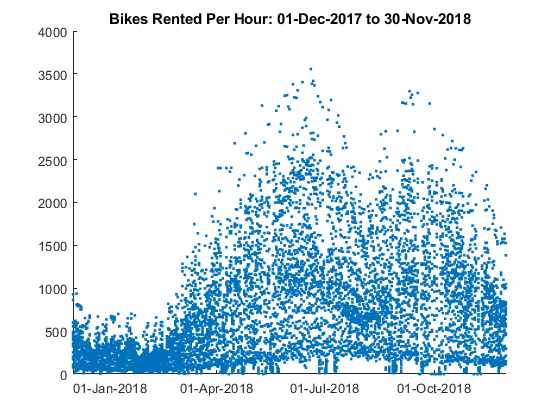

% inputs are all of datamat except col 2
datasetInputs=datamat;
datasetInputs(:,2)=[];
datasetOutputs=datamat(:,2);

onedayavg = movmean(datasetOutputs,[23,0]);
sevendayavg = movmean(datasetOutputs,[(7*24-1) 0]); % 7-day average up til now
thirtydayavg = movmean(datasetOutputs,[(30*24-1) 0]); % 30-day avg up til now

onedaymax = movmax(datasetOutputs,[23,0]);
sevendaymax = movmax(datasetOutputs,[(7*24-1) 0]); % 7-day max up til now
thirtydaymax = movmax(datasetOutputs,[(30*24-1) 0]); % 30-day max up til now

for ii=1:15
    onedayavg_in(:,ii) = movmean(datasetInputs(:,ii),[23,0]);
    sevendayavg_in(:,ii) = movmean(datasetInputs(:,ii),[(7*24-1) 0]); % 7-day average up til now
    thirtydayavg_in(:,ii) = movmean(datasetInputs(:,ii),[(30*24-1) 0]); % 30-day avg up til now

    onedaymax_in(:,ii) = movmax(datasetInputs(:,ii),[23,0]);
    sevendaymax_in(:,ii) = movmax(datasetInputs(:,ii),[(7*24-1) 0]); % 7-day max up til now
    thirtydaymax_in(:,ii) = movmax(datasetInputs(:,ii),[(30*24-1) 0]); % 30-day max up til now
end

dateslist = datetime(datamat(:,1),'ConvertFrom','datenum');

figure
scatter(dateslist, datasetOutputs,'.')
xtickformat('dd-MMM-yyyy')
title(['Bikes Rented Per Hour: ' datestr(dateslist(1)) ' to ' datestr(dateslist(end))])

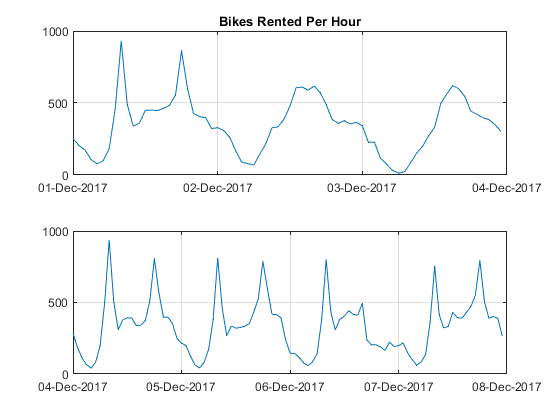

figure
subplot(2,1,1)
plot(dateslist(1:(3*24))+(1/24)*datamat(1:(3*24),3), datasetOutputs(1:(3*24)))
xtickformat('dd-MMM-yyyy')
grid on
title('Bikes Rented Per Hour')
subplot(2,1,2)
plot(dateslist((3*24+1):(7*24))+(1/24)*datamat((3*24+1):(7*24),3), datasetOutputs((3*24+1):(7*24)))
xtickformat('dd-MMM-yyyy')
grid on

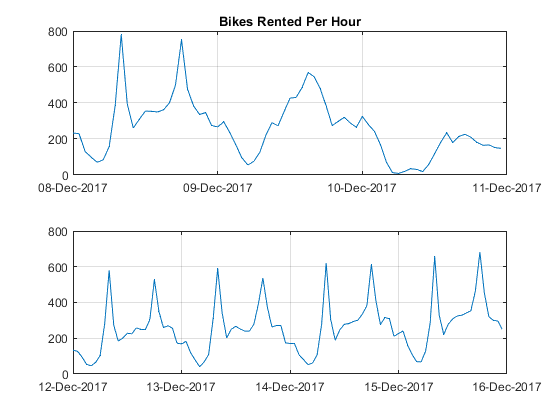


figure
subplot(2,1,1)
plot(dateslist((7*24+1):(10*24))+(1/24)*datamat((7*24+1):(10*24),3), datasetOutputs((7*24+1):(10*24)))
xtickformat('dd-MMM-yyyy')
grid on
title('Bikes Rented Per Hour')
subplot(2,1,2)
plot(dateslist((11*24+1):(15*24))+(1/24)*datamat((11*24+1):(15*24),3), datasetOutputs((11*24+1):(15*24)))
xtickformat('dd-MMM-yyyy')
grid on

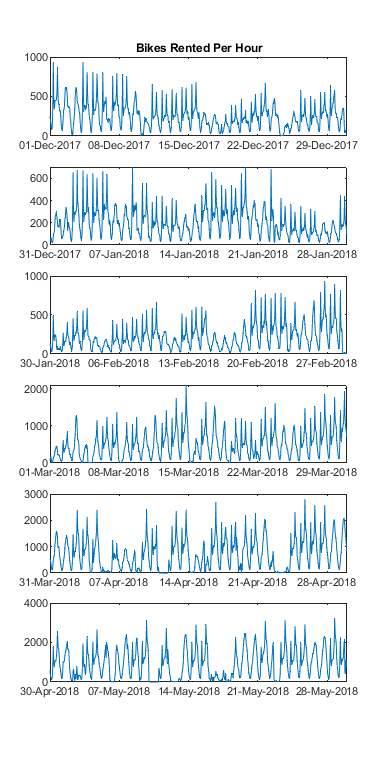

% Weekdays have two peaks: one in the morning and one in the evening;
% weekend days have one peak in the afternoon. Similar patterns are seen in
% the plots below, except for Sept 18-26.  Minimal rentals in the early
% morning, but not 0. Unclear whether the data is how many bike rentals are
% initiated during each hour or whether the count includes bikes which were
% rented earlier for multiple hours.

figure('Renderer', 'painters', 'Position', [10 10 800 1600])
for i=1:6
subplot(6,1,i)
im=i-1;
plot(dateslist((im*30*24+1):(i*30*24))+(1/24)*datamat((im*30*24+1):(i*30*24),3), datasetOutputs((im*30*24+1):(i*30*24)))
xtickformat('dd-MMM-yyyy')
if i==1
    title('Bikes Rented Per Hour')
end
end

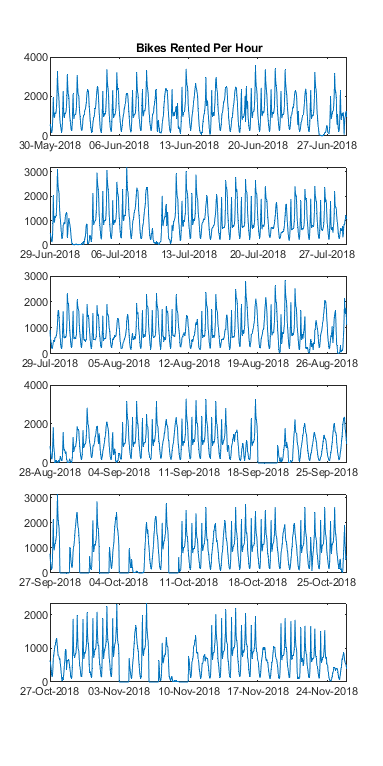



figure('Renderer', 'painters', 'Position', [10 10 800 1600])
for i=7:12
subplot(6,1,(i-6))
im=i-1;
plot(dateslist((im*30*24+1):(i*30*24))+(1/24)*datamat((im*30*24+1):(i*30*24),3), datasetOutputs((im*30*24+1):(i*30*24)))
xtickformat('dd-MMM-yyyy')
if i==7
    title('Bikes Rented Per Hour')
end
end

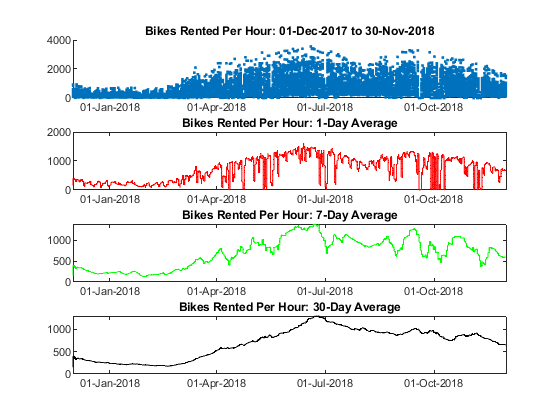



figure
subplot(4,1,1)
scatter(dateslist, datasetOutputs,'.')
hold on
xtickformat('dd-MMM-yyyy')
title(['Bikes Rented Per Hour: ' datestr(dateslist(1)) ' to ' datestr(dateslist(end))])
subplot(4,1,2)
plot(dateslist, onedayavg,'r')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 1-Day Average')
subplot(4,1,3)
plot(dateslist, sevendayavg,'g')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 7-Day Average')
subplot(4,1,4)
plot(dateslist, thirtydayavg,'k')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 30-Day Average')

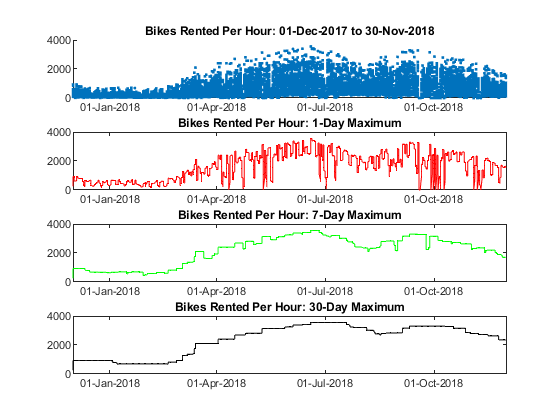


figure
subplot(4,1,1)
scatter(dateslist, datasetOutputs,'.')
hold on
xtickformat('dd-MMM-yyyy')
title(['Bikes Rented Per Hour: ' datestr(dateslist(1)) ' to ' datestr(dateslist(end))])
subplot(4,1,2)
plot(dateslist, onedaymax,'r')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 1-Day Maximum')
subplot(4,1,3)
plot(dateslist, sevendaymax,'g')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 7-Day Maximum')
subplot(4,1,4)
plot(dateslist, thirtydaymax,'k')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 30-Day Maximum')

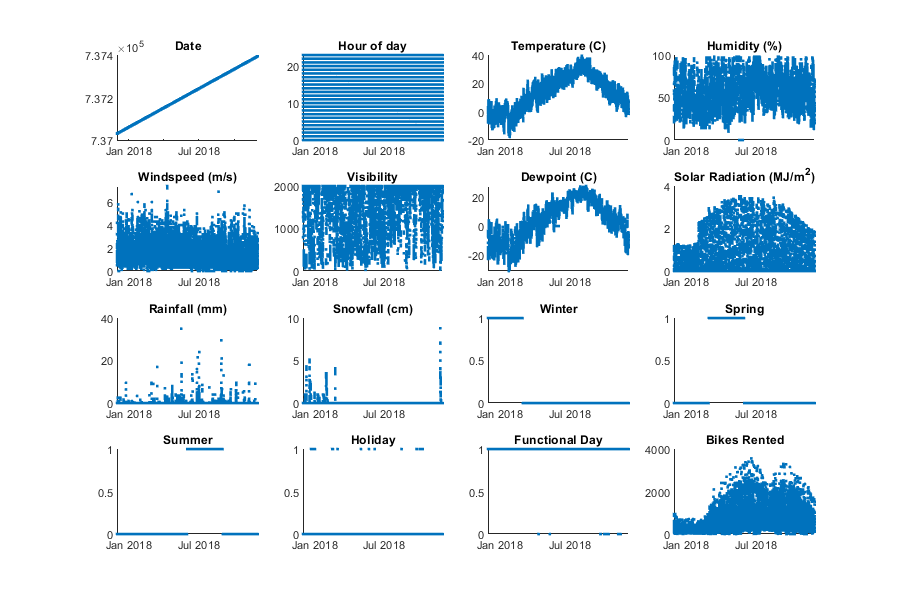

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(4,4,1)
scatter(dateslist, datasetInputs(:,1),'.')
title('Date')
subplot(4,4,2)
scatter(dateslist, datasetInputs(:,2),'.')
title('Hour of day')
subplot(4,4,3)
scatter(dateslist, datasetInputs(:,3),'.')
title('Temperature (C)')
subplot(4,4,4)
scatter(dateslist, datasetInputs(:,4),'.')
title('Humidity (%)')
subplot(4,4,5)
scatter(dateslist, datasetInputs(:,5),'.')
title('Windspeed (m/s)')
subplot(4,4,6)
scatter(dateslist, datasetInputs(:,6),'.')
title('Visibility')
subplot(4,4,7)
scatter(dateslist, datasetInputs(:,7),'.')
title('Dewpoint (C)')
subplot(4,4,8)
scatter(dateslist, datasetInputs(:,8),'.')
title('Solar Radiation (MJ/m^2)')
subplot(4,4,9)
scatter(dateslist, datasetInputs(:,9),'.')
title('Rainfall (mm)')
subplot(4,4,10)
scatter(dateslist, datasetInputs(:,10),'.')
title('Snowfall (cm)')
subplot(4,4,11)
scatter(dateslist, datasetInputs(:,11),'.')
title('Winter')
subplot(4,4,12)
scatter(dateslist, datasetInputs(:,12),'.')
title('Spring')
subplot(4,4,13)
scatter(dateslist, datasetInputs(:,13),'.')
title('Summer')
subplot(4,4,14)
scatter(dateslist, datasetInputs(:,14),'.')
title('Holiday')
subplot(4,4,15)
scatter(dateslist, datasetInputs(:,15),'.')
title('Functional Day')
subplot(4,4,16)
scatter(dateslist, datasetOutputs,'.')
title('Bikes Rented')

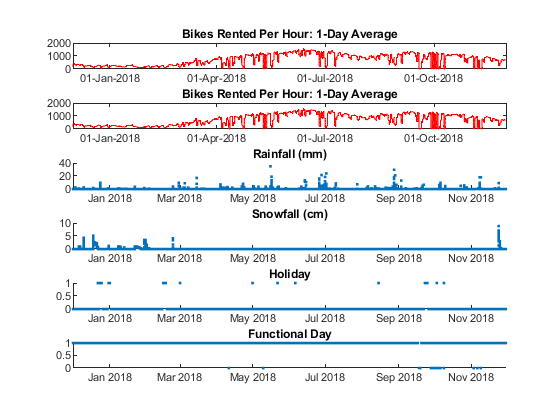

varnames={'Date','Hour','Temp','Hum','Windsp','Vis','Dewpt','SolRad','Rain','Snow','Winter','Spring','Summer','Hol','Func'};

figure
subplot(6,1,1)
plot(dateslist, onedayavg,'r')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 1-Day Average')
subplot(6,1,2)
plot(dateslist, onedayavg,'r')
xtickformat('dd-MMM-yyyy')
title('Bikes Rented Per Hour: 1-Day Average')
subplot(6,1,3)
scatter(dateslist, datasetInputs(:,9),'.')
title('Rainfall (mm)')
subplot(6,1,4)
scatter(dateslist, datasetInputs(:,10),'.')
title('Snowfall (cm)')
subplot(6,1,5)
scatter(dateslist, datasetInputs(:,14),'.')
title('Holiday')
subplot(6,1,6)
scatter(dateslist, datasetInputs(:,15),'.')
title('Functional Day')

% Nonfunctional days and spring/summer rainfall days seem to correlate with
% spikiness of bike rental distribution. 

% Normalize the inputs
datasetInputs_orig = datasetInputs;
datasetInputs = mapminmax(datasetInputs_orig')';
testmax=max(datasetInputs');
testmin=min(datasetInputs');

% Linear Regression on Bikes Rented vs. Solar Radiation
mdl_linear = fitlm(datasetInputs(:,8),datasetOutputs)

mdl_linear = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat       pValue   
                   ________    ______    ______    ___________

    (Intercept)     936.11     11.286    82.942              0
    x1              342.14     13.476     25.39    2.7804e-137


Number of observations: 8760, Error degrees of freedom: 8758
Root Mean Squared Error: 623
R-squared: 0.0686,  Adjusted R-Squared: 0.0685
F-statistic vs. constant model: 645, p-value = 2.78e-137

predicted = predict(mdl_linear,datasetInputs(:,8));
RMSE_linearmodel = sqrt(mean((predicted-datasetOutputs).^2))

RMSE_linearmodel = 622.4593

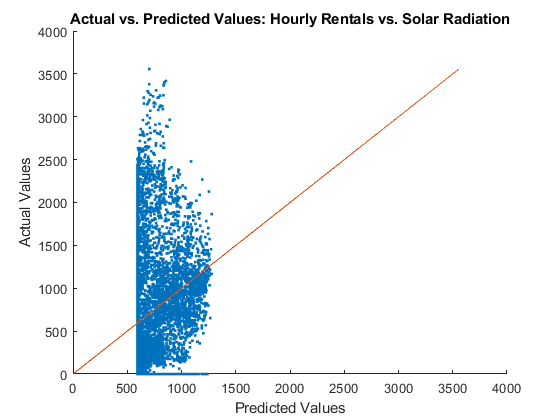

figure
scatter(predicted, datasetOutputs,'.')
hold on
plot(datasetOutputs,datasetOutputs)
title('Actual vs. Predicted Values: Hourly Rentals vs. Solar Radiation')
ylabel('Actual Values')
xlabel('Predicted Values')

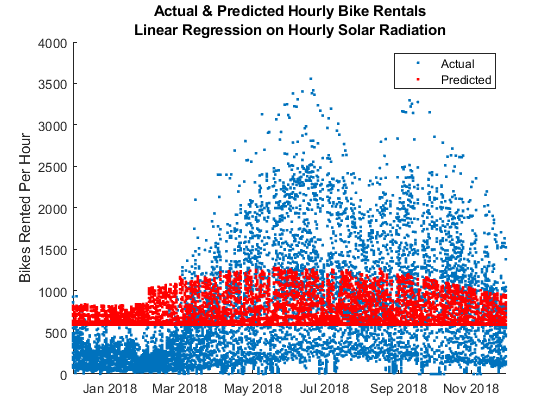


figure
scatter(dateslist,datasetOutputs,'.')
hold on
scatter(dateslist,predicted,'.r')
title({'Actual & Predicted Hourly Bike Rentals','Linear Regression on Hourly Solar Radiation'})
ylabel('Bikes Rented Per Hour')
legend({'Actual','Predicted'})

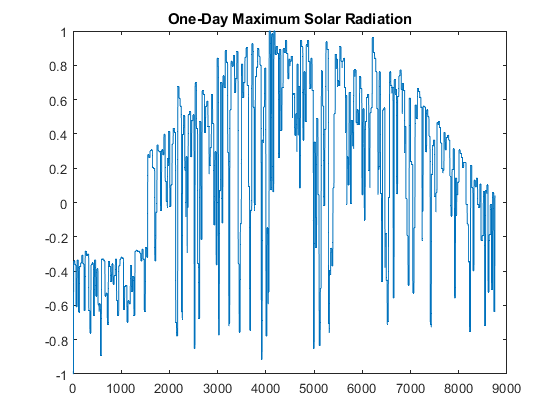



onedaymax_sol = movmax(datasetInputs(:,8),[23,0]);
sevendaymax_sol = movmax(datasetInputs(:,8),[(7*24-1) 0]); % 7-day max up til now
onedaymax_temp = movmax(datasetInputs(:,3),[23,0]);
sevendaymax_temp = movmax(datasetInputs(:,3),[(7*24-1) 0]); % 7-day max up til now
sevendaymean_vis = movmean(datasetInputs(:,6),[(7*24-1) 0]); % 7-day max up til now
sevendaymean_hum = movmean(datasetInputs(:,4),[(7*24-1) 0]); % 7-day max up til now

figure
plot(onedaymax_sol)
title('One-Day Maximum Solar Radiation')

mdl_linear2 = fitlm(onedaymax_sol,onedaymax)

mdl_linear2 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat     pValue
                   ________    ______    ______    ______

    (Intercept)     1452.2     8.1682    177.78      0   
    x1              1169.7     15.128    77.323      0   


Number of observations: 8760, Error degrees of freedom: 8758
Root Mean Squared Error: 711
R-squared: 0.406,  Adjusted R-Squared: 0.406
F-statistic vs. constant model: 5.98e+03, p-value = 0

predicted2 = predict(mdl_linear2,onedaymax_sol);
RMSE_linearmodel2 = sqrt(mean((predicted2-onedaymax).^2))

RMSE_linearmodel2 = 710.8259

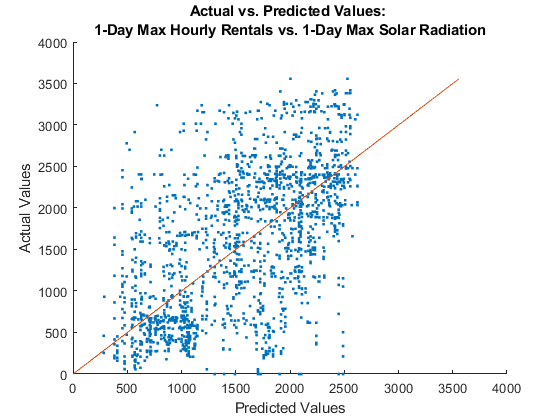

figure
scatter(predicted2, onedaymax,'.')
hold on
plot(onedaymax,onedaymax)
title({'Actual vs. Predicted Values: ';'1-Day Max Hourly Rentals vs. 1-Day Max Solar Radiation'})
ylabel('Actual Values')
xlabel('Predicted Values')

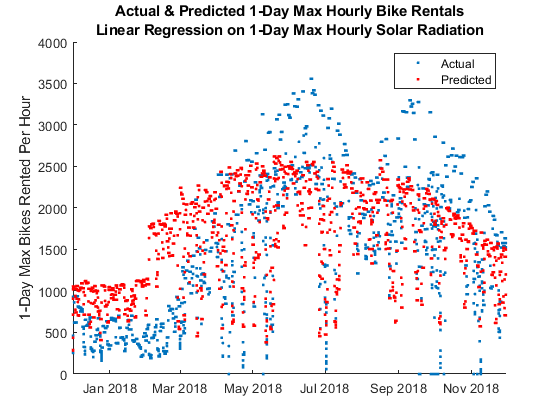

figure
scatter(dateslist,onedaymax,'.')
hold on
scatter(dateslist,predicted2,'.r')
title({'Actual & Predicted 1-Day Max Hourly Bike Rentals','Linear Regression on 1-Day Max Hourly Solar Radiation'})
ylabel('1-Day Max Bikes Rented Per Hour')
legend({'Actual','Predicted'})


mdl_linear3 = fitlm(sevendaymax_sol,sevendaymax)

mdl_linear3 = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat     pValue
                   ________    ______    ______    ______

    (Intercept)     1285.2     9.0889     141.4      0   
    x1              1795.6     13.662    131.43      0   


Number of observations: 8760, Error degrees of freedom: 8758
Root Mean Squared Error: 566
R-squared: 0.664,  Adjusted R-Squared: 0.664
F-statistic vs. constant model: 1.73e+04, p-value = 0

predicted3 = predict(mdl_linear3,sevendaymax_sol);
RMSE_linearmodel3 = sqrt(mean((predicted3-sevendaymax).^2))

RMSE_linearmodel3 = 565.8367

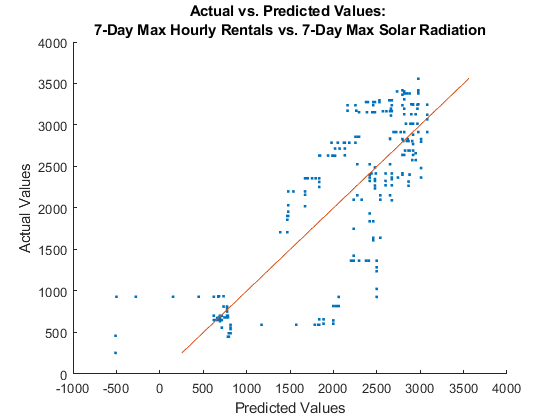

figure
scatter(predicted3, sevendaymax,'.')
hold on
plot(sevendaymax,sevendaymax)
title({'Actual vs. Predicted Values: ';'7-Day Max Hourly Rentals vs. 7-Day Max Solar Radiation'})
ylabel('Actual Values')
xlabel('Predicted Values')

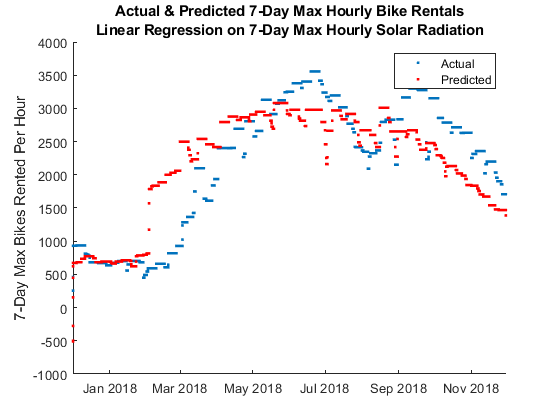

figure
scatter(dateslist,sevendaymax,'.')
hold on
scatter(dateslist,predicted3,'.r')
title({'Actual & Predicted 7-Day Max Hourly Bike Rentals','Linear Regression on 7-Day Max Hourly Solar Radiation'})
ylabel('7-Day Max Bikes Rented Per Hour')
legend({'Actual','Predicted'})

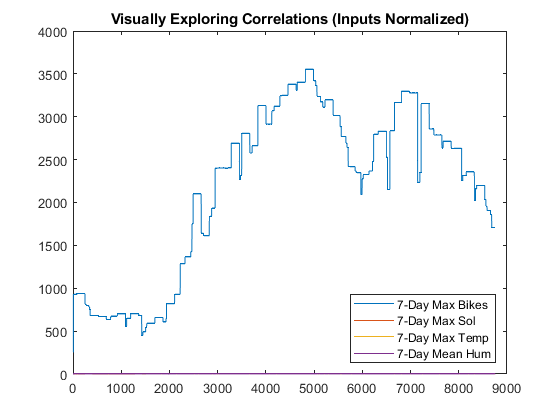


figure
plot(sevendaymax)
hold on
plot(sevendaymax_sol)
plot(sevendaymax_temp)
%plot(2*sevendaymean_vis)
plot(sevendaymean_hum)
title('Visually Exploring Correlations (Inputs Normalized)')
legend({'7-Day Max Bikes','7-Day Max Sol','7-Day Max Temp', '7-Day Mean Hum'},'Location','Southeast')

mdl_linear4 = fitlm([sevendaymax_sol,sevendaymax_temp,sevendaymean_hum],sevendaymax)

mdl_linear4 = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate      SE      tStat       pValue   
                   ________    ______    ______    ___________

    (Intercept)     1208.5     7.9017    152.94              0
    x1               717.8     20.165    35.597    2.5041e-259
    x2              1409.7     26.829    52.543              0
    x3              485.74     31.517    15.412     6.6783e-53


Number of observations: 8760, Error degrees of freedom: 8756
Root Mean Squared Error: 448
R-squared: 0.789,  Adjusted R-Squared: 0.789
F-statistic vs. constant model: 1.09e+04, p-value = 0

predicted4 = predict(mdl_linear4,[sevendaymax_sol,sevendaymax_temp,sevendaymean_hum]);
RMSE_linearmodel4 = sqrt(mean((predicted4-sevendaymax).^2))

RMSE_linearmodel4 = 448.1754

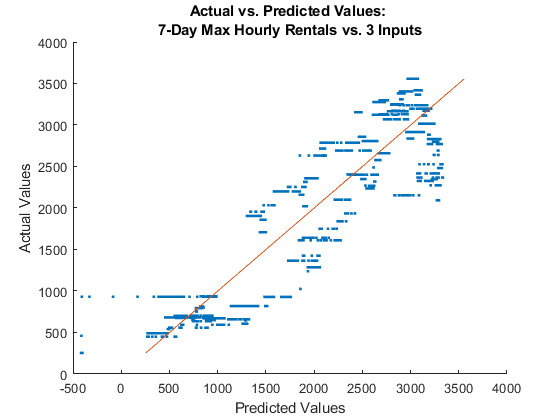

figure
scatter(predicted4, sevendaymax,'.')
hold on
plot(sevendaymax,sevendaymax)
title({'Actual vs. Predicted Values: ';'7-Day Max Hourly Rentals vs. 3 Inputs'})
ylabel('Actual Values')
xlabel('Predicted Values')

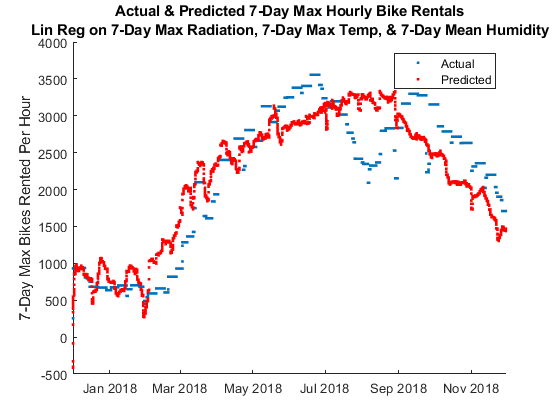

figure
scatter(dateslist,sevendaymax,'.')
hold on
scatter(dateslist,predicted4,'.r')
title({'Actual & Predicted 7-Day Max Hourly Bike Rentals','Lin Reg on 7-Day Max Radiation, 7-Day Max Temp, & 7-Day Mean Humidity'})
ylabel('7-Day Max Bikes Rented Per Hour')
legend({'Actual','Predicted'})


% Linear regressions with all available variables

% raw hourly counts
mdl_linear_raw = fitlm(datasetInputs,datasetOutputs)

mdl_linear_raw = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate      SE       tStat       pValue   
                   ________    ______    _______    ___________

    (Intercept)    -1052.2     93.778     -11.22     5.1332e-29
    x1             -266.48      32.09    -8.3042     1.1546e-16
    x2              314.19     8.4216     37.308    7.8268e-283
    x3               483.6     104.38     4.6332     3.6523e-06
    x4             -540.23     50.274    -10.746     9.1165e-27
    x5              70.763      18.78     3.7681      0.0001656
    x6              6.0309     9.7223    0.62031        0.53507
    

% 1-day average
mdl_linear_1avg = fitlm(onedayavg_in,onedayavg)

mdl_linear_1avg = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                    Estimate        SE        tStat       pValue   
                   __________    ________    _______    ___________

    (Intercept)    7.6489e+05       52398     14.598     1.0549e-47
    x1                -1.0359    0.071065    -14.576     1.4343e-47
    x2                -6.9071      5.2283    -1.3211        0.18651
    x3                -35.609      3.0002    -11.869     3.0258e-32
    x4                -15.954     0.87052    -18.327     1.1921e-73
    x5                 -39.01      3.4417    -11.334     1.4231e-29
    x6              -0.035788    0.005066

% 7-day avg
mdl_linear_7avg = fitlm(sevendayavg_in,sevendayavg)

mdl_linear_7avg = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                    Estimate        SE         tStat       pValue   
                   __________    _________    _______    ___________

    (Intercept)    9.7489e+05        38407     25.383     3.317e-137
    x1                -1.3202     0.052078    -25.351    7.0785e-137
    x2                -17.869       3.3656    -5.3093     1.1278e-07
    x3                -56.986       3.8756    -14.704      2.294e-48
    x4                -16.531       1.1839    -13.963     7.7093e-44
    x5                -160.58       5.5438    -28.966    3.0855e-176
    x6              -0.022649    

% 30-day avg
mdl_linear_30avg = fitlm(thirtydayavg_in,thirtydayavg)

mdl_linear_30avg = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                    Estimate        SE         tStat       pValue   
                   __________    _________    _______    ___________

    (Intercept)    2.0713e+06        30885     67.065              0
    x1                -2.8052     0.041861    -67.012              0
    x2                -2.7316       2.0329    -1.3437        0.17908
    x3                -48.314       3.5637    -13.557     1.8811e-41
    x4                -34.621       1.1103    -31.182    1.7066e-202
    x5                -342.57       6.2549    -54.768              0
    x6               -0.33586   

% 1-day max
mdl_linear_1max = fitlm(onedaymax_in,onedaymax)

mdl_linear_1max = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                    Estimate        SE         tStat       pValue   
                   __________    _________    _______    ___________

    (Intercept)    8.4179e+05    1.356e+05      6.208     5.6095e-10
    x1                -1.1434      0.18392    -6.2171     5.2949e-10
    x2                -20.386       7.7117    -2.6434      0.0082214
    x3                 50.018       2.5369     19.716     1.0677e-84
    x4                 4.3136      0.69235     6.2304     4.8677e-10
    x5                -14.424       5.9198    -2.4365        0.01485
    x6               0.016246    

% 7-day max
mdl_linear_7max = fitlm(sevendaymax_in,sevendaymax)

mdl_linear_7max = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate       SE        tStat        pValue   
                   ________    ________    ________    ___________

    (Intercept)      -19515       71823    -0.27172        0.78585
    x1             0.024908    0.097382     0.25577        0.79813
    x2              -62.226      5.8839     -10.576     5.5452e-26
    x3               30.865      2.0078      15.372     1.2197e-52
    x4               13.664     0.89131       15.33     2.3004e-52
    x5              -34.949      4.7475     -7.3616     1.9813e-13
    x6               1.2599     0.29544      4.26

% 30-day max
mdl_linear_30max = fitlm(thirtydaymax_in,thirtydaymax)

mdl_linear_30max = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)          0            0        NaN            NaN
    x1               2.165     0.055961     38.689    2.0964e-302
    x2              -77.31       7.7162    -10.019     1.6812e-23
    x3             -24.829       1.8692    -13.283     7.0321e-40
    x4              15.776       2.1327     7.3969     1.5227e-13
    x5             -93.404       3.0229    -30.898    4.7537e-199
    x6              -796.7       20.624    -38.629    1.

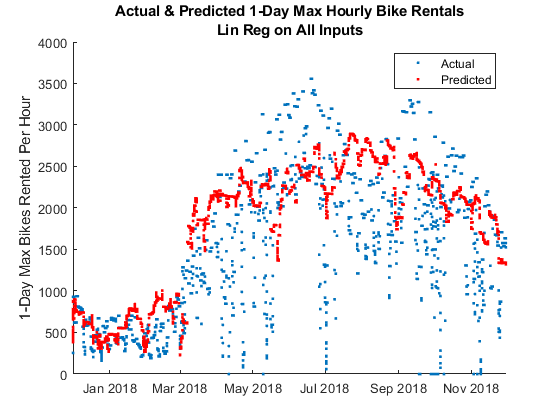

predicted_1avg = predict(mdl_linear_1avg,sevendayavg_in);
predicted_7avg = predict(mdl_linear_7avg,sevendayavg_in);
predicted_30avg = predict(mdl_linear_30avg,thirtydayavg_in);
predicted_1max = predict(mdl_linear_1max,sevendaymax_in);
predicted_7max = predict(mdl_linear_7max,sevendaymax_in);
predicted_30max = predict(mdl_linear_30max,thirtydaymax_in);

figure
scatter(dateslist,onedaymax,'.')
hold on
scatter(dateslist,predicted_1max,'.r')
title({'Actual & Predicted 1-Day Max Hourly Bike Rentals','Lin Reg on All Inputs'})
ylabel('1-Day Max Bikes Rented Per Hour')
legend({'Actual','Predicted'})

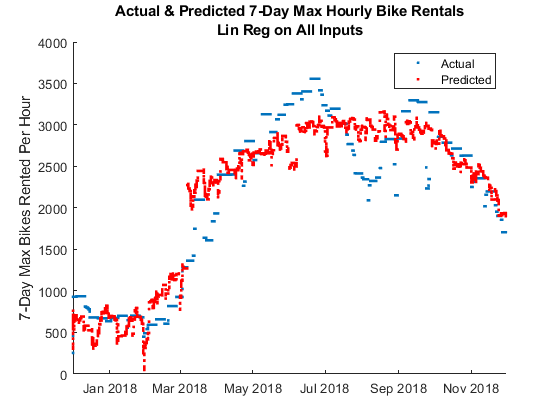


figure
scatter(dateslist,sevendaymax,'.')
hold on
scatter(dateslist,predicted_7max,'.r')
title({'Actual & Predicted 7-Day Max Hourly Bike Rentals','Lin Reg on All Inputs'})
ylabel('7-Day Max Bikes Rented Per Hour')
legend({'Actual','Predicted'})

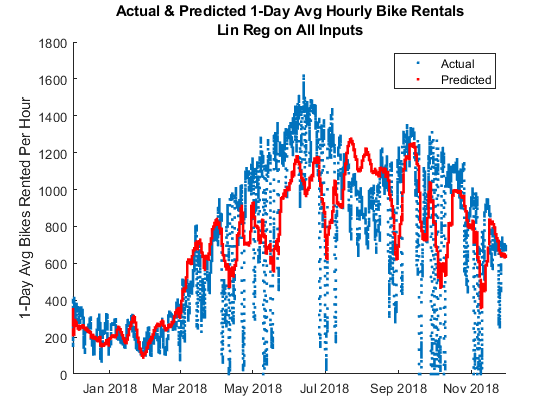

figure
scatter(dateslist,onedayavg,'.')
hold on
scatter(dateslist,predicted_1avg,'.r')
title({'Actual & Predicted 1-Day Avg Hourly Bike Rentals','Lin Reg on All Inputs'})
ylabel('1-Day Avg Bikes Rented Per Hour')
legend({'Actual','Predicted'})

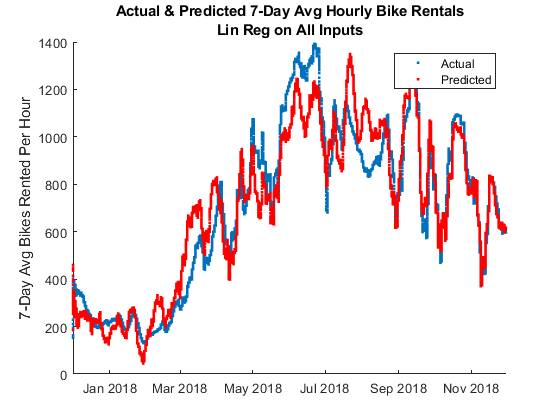


figure
scatter(dateslist,sevendayavg,'.')
hold on
scatter(dateslist,predicted_7avg,'.r')
title({'Actual & Predicted 7-Day Avg Hourly Bike Rentals','Lin Reg on All Inputs'})
ylabel('7-Day Avg Bikes Rented Per Hour')
legend({'Actual','Predicted'})

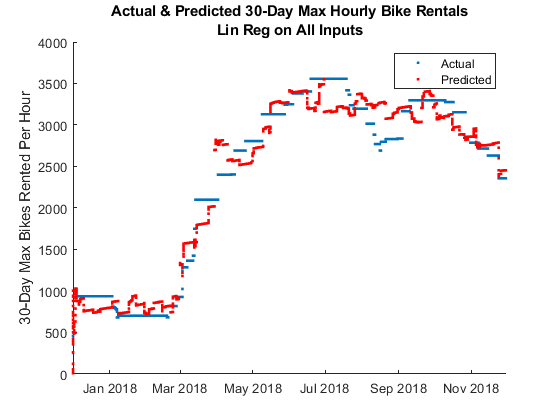


figure
scatter(dateslist,thirtydaymax,'.')
hold on
scatter(dateslist,predicted_30max,'.r')
title({'Actual & Predicted 30-Day Max Hourly Bike Rentals','Lin Reg on All Inputs'})
ylabel('30-Day Max Bikes Rented Per Hour')
legend({'Actual','Predicted'})

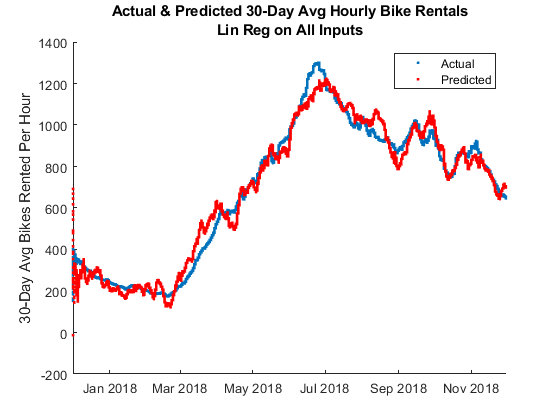


figure
scatter(dateslist,thirtydayavg,'.')
hold on
scatter(dateslist,predicted_30avg,'.r')
title({'Actual & Predicted 30-Day Avg Hourly Bike Rentals','Lin Reg on All Inputs'})
ylabel('30-Day Avg Bikes Rented Per Hour')
legend({'Actual','Predicted'})

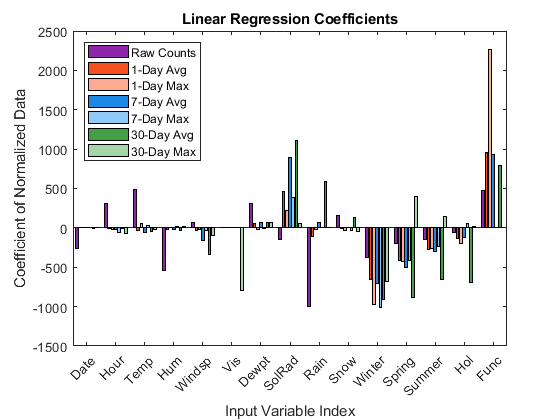

% Compare coefficients
coeff_raw = mdl_linear_raw.Coefficients.Estimate(2:end);
coeff_1max = mdl_linear_1max.Coefficients.Estimate(2:end);
coeff_7max = mdl_linear_7max.Coefficients.Estimate(2:end);
coeff_30max = mdl_linear_30max.Coefficients.Estimate(2:end);
coeff_1avg = mdl_linear_1avg.Coefficients.Estimate(2:end);
coeff_7avg = mdl_linear_7avg.Coefficients.Estimate(2:end);
coeff_30avg = mdl_linear_30avg.Coefficients.Estimate(2:end);

figure
h=bar([coeff_raw,coeff_1avg,coeff_1max,coeff_7avg,coeff_7max,coeff_30avg,coeff_30max]);
h(1).FaceColor='#8e24aa';
h(2).FaceColor='#f4511e';
h(3).FaceColor='#ffab91';
h(4).FaceColor='#1e88e5';
h(5).FaceColor='#90caf9';
h(6).FaceColor='#43a047';
h(7).FaceColor='#a5d6a7';
legend({'Raw Counts','1-Day Avg','1-Day Max','7-Day Avg','7-Day Max','30-Day Avg','30-Day Max'},'Location','Northwest')
title('Linear Regression Coefficients')
xlabel('Input Variable Index')
ylabel('Coefficient of Normalized Data')
set(gca,'XTickLabel',varnames)
xtickangle(45)
set(gca,'XTick',1:15)